clear

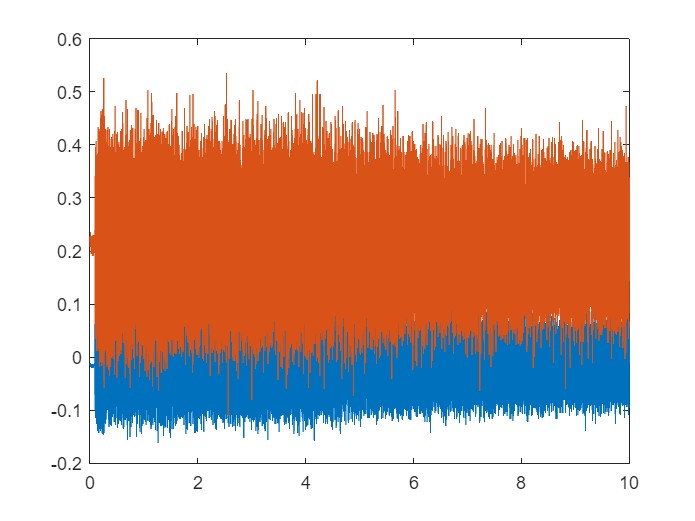

% Import audio
[data, fs] = audioread("C:\Users\sucho\Desktop\Semestr-8\signals\Labs\Lab3\GrupaNadzieja.wav");

N=length(data);
dt=1/fs;
t=(0:N-1)*dt;

plot(t,data(:,1),t,data(:,2));

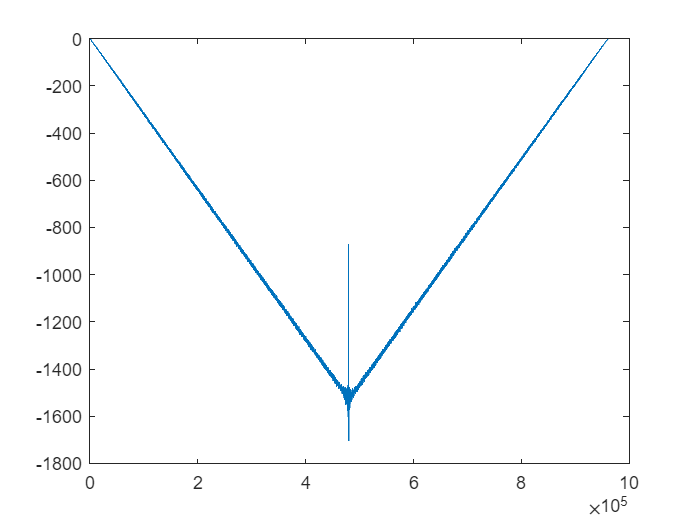



[r  lags]= xcorr(data(:,1),data(:,2));

plot(r)

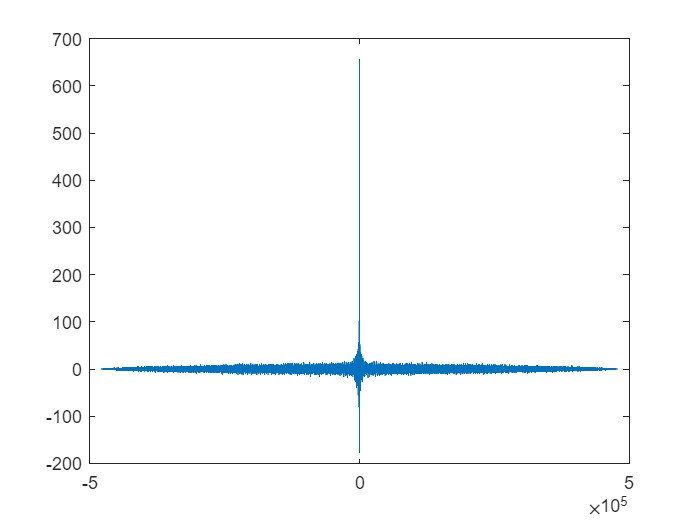


% sound(data(:,1),fs)

y1=data(:,1)-mean(data(:,1));
y2=data(:,2)-mean(data(:,2));

r = xcorr(y1,y2);

plot(lags,r)


[val,pos]=max(r)

val = 656.6155

pos = 479841


time_lag=lags(pos)/fs;

dist=1.15;

speed=-1.15/time_lag

speed = -347.1698

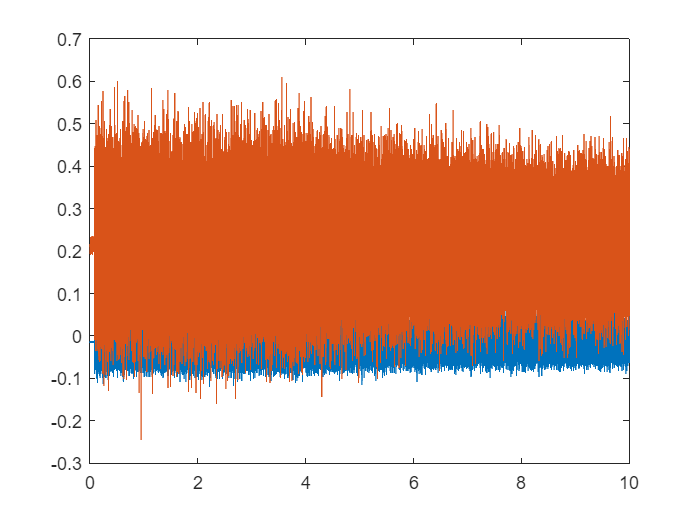

clear
peak_dist=1.01;

[data,fs]=audioread("Lab3\Setup2_SSMWMS.wav");

N=length(data);
dt=1/fs;
t=(0:N-1)*dt;

plot(t,data(:,1),t,data(:,2));

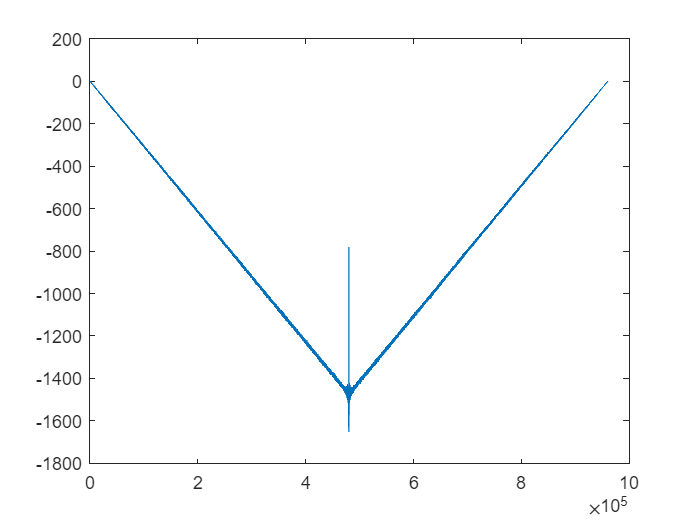



[r,lags]= xcorr(data(:,1),data(:,2));

plot(r)

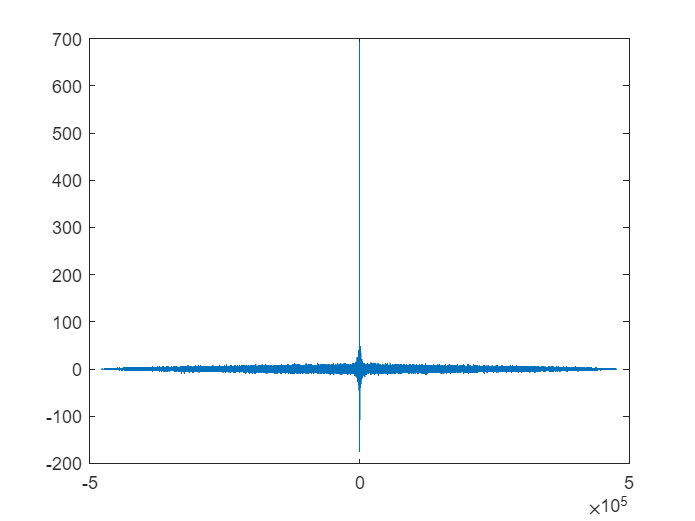


% sound(data(:,1),fs)

y1=data(:,1)-mean(data(:,1));
y2=data(:,2)-mean(data(:,2));

r = xcorr(y1,y2);

plot(lags,r)


[val,pos]=max(r)

val = 692.8350

pos = 479997


time_lag=lags(pos)/fs

time_lag = -6.2500e-05


dist=1.01;

speed=-1.01/time_lag

speed = 16160

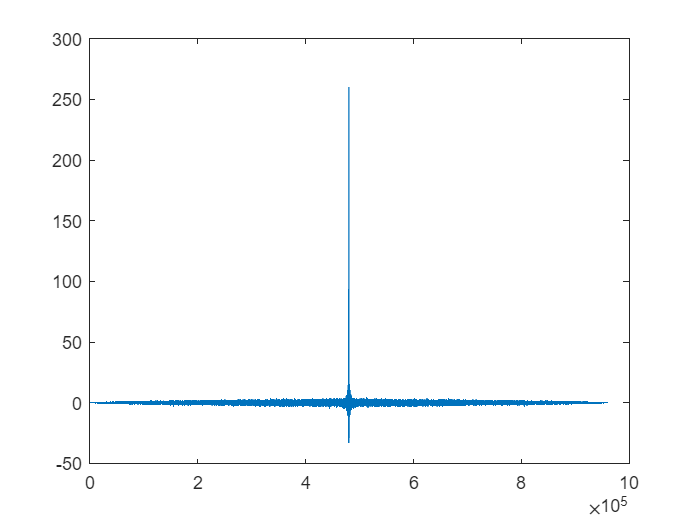


plot(xcorr(y1))


[r1,lag1] = xcorr(y1);
[r2,lag2] = xcorr(y2);




[val1,pos1]=max(xcorr(y1))

val1 = 260.1919

pos1 = 480000

[val2,pos2]=max(xcorr(y2))

val2 = 3.2540e+03

pos2 = 480000


time_lag1=lags(pos)/fs
